clear
load('Data4Test.mat')
[Hpar] = GetParameters();

% Parameters can be changed for better performancing.
Hpar.mu = 0.0002; %
Hpar.lm = 0.01; %

SCWR test

[Yv_fit,Ind_W,finalN,Ar] = SCWR(Xv,Xc,Yc,Hpar);
% Yv_fit: fitted values
% Ind_W: Index of selected wavelengths
% finalN: Number of selected wavelengths
% Ar: Sparse regression coefficients 
R2P_SR= GetR2(Yv_fit,Yv)

R2P_SR =     0.8711    0.7381    0.8618    0.9464


RMSEP_SR = GetRMSE(Yv_fit,Yv)

RMSEP_SR =     0.1560    0.0925    0.1648    0.1965


para = 0.07

para = 0.0700

Range_LVs = 25;
[Yv_fit,Ind_W,B,finalN,OH,RMSECV] = SPLSR(Xc,Xv,Yc,Range_LVs,para,10)

Yv_fit =    10.0149    3.7782    8.9835   64.4865
   10.6011    3.2790    8.0019   65.1568
   10.1111    3.6018    8.3239   64.8485
   10.7364    3.3954    8.1346   65.1457
    9.4889    3.4756    8.6730   64.4715
    9.7436    3.6696    8.5990   65.4821
   10.4488    3.6568    8.5619   65.2946
   10.1496    3.6001    8.3513   65.0683
   10.3937    3.5838    9.2678   62.9666
    9.8516    3.3227    9.3638   63.6345


Ind_W =      1     1     1     1
     2     2     2     2
     3     3     3     3
     4     4     4     4
     5     5     5     5
     6     6     6     6
     7     7     7     7
     8     8     8     8
     9     9     9     9
    10    10    10    10


B =    -9.8697   -8.6672   -5.3661    0.9131
   -8.5078   -7.7613   -4.5186    0.8254
   -8.5209   -7.7733   -4.5256    0.8266
   -8.4454   -7.7044   -4.4855    0.8193
   -8.3812   -7.6458   -4.4514    0.8131
   -8.3111   -7.5819   -4.4142    0.8063
   -8.2997   -7.5715   -4.4081    0.8052
   -8.1961   -7.4770   -4.3531    0.7951
   -8.0257   -7.3216   -4.2626    0.7786
   -7.8950   -7.2023   -4.1932    0.7659


finalN =    623   623   623   623


OH = 24

RMSECV =     1.0023    0.9724    0.8138    0.7303    0.6862    0.5326    0.4521    0.4564    0.4480    0.4382    0.4067    0.4065    0.3982    0.3798    0.3930    0.3930    0.4140    0.4241    0.4322    0.4126    0.3781    0.3775    0.3700    0.3570    0.3570


% Yv_fit: fitted values
% Ind_W: Index of selected wavelengths
% finalN: Number of selected wavelengths
% B: Regression coefficients 
% OH: Optimal number of LVs
% RMSECV for a range of LVs
R2P_SR= GetR2(Yv_fit,Yv)

R2P_SR =     0.8869    0.7533    0.8284    0.9598


RMSEP_SR = GetRMSE(Yv_fit,Yv)

RMSEP_SR =     0.1462    0.0898    0.1837    0.1702


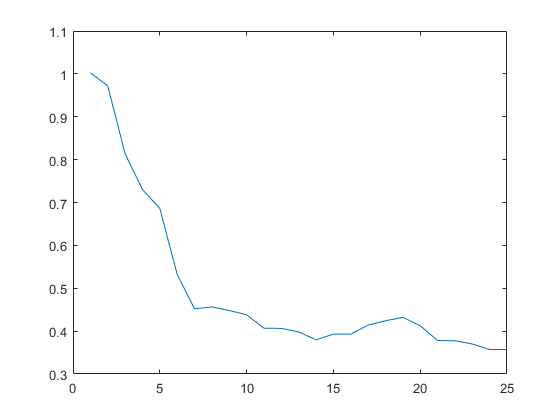

plot([1:Range_LVs],RMSECV)

% Reference
% Lei, T., & Sun, D. W. (2020). A novel NIR spectral calibration method: sparse coefficients wavelength selection and regression (SCWR). Analytica chimica acta, 1110, 169-180.